# stability analysis across sep and exp in CaMKII

#### 0 pre-processing 

load('CMK_dTT_PCA.mat')
N=length(Ee);
dis_th=40;
[Ee,~]=remove_contamination(Ee,dis_th);

ans = 'Pair1,Mouse1,69(30%) cells removed'

ans = 'Pair1,Mouse2,77(48%) cells removed'

ans = 'Pair2,Mouse1,66(38%) cells removed'

ans = 'Pair2,Mouse2,80(41%) cells removed'

ans = 'Pair3,Mouse1,77(45%) cells removed'

ans = 'Pair3,Mouse2,58(30%) cells removed'

ans = 'Pair4,Mouse1,46(30%) cells removed'

ans = 'Pair4,Mouse2,41(18%) cells removed'

ans = 'Pair5,Mouse1,41(23%) cells removed'

ans = 'Pair5,Mouse2,28(14%) cells removed'

ans = 'Pair6,Mouse1,60(39%) cells removed'

ans = 'Pair6,Mouse2,64(44%) cells removed'

ans = 'Pair7,Mouse1,43(24%) cells removed'

ans = 'Pair7,Mouse2,67(29%) cells removed'

ans = 'Pair8,Mouse1,31(19%) cells removed'

ans = 'Pair8,Mouse2,56(33%) cells removed'

ans = 'Pair9,Mouse1,39(20%) cells removed'

ans = 'Pair9,Mouse2,51(31%) cells removed'

[Es,~]=remove_contamination(Es,dis_th);

ans = 'Pair1,Mouse1,50(23%) cells removed'

ans = 'Pair1,Mouse2,59(40%) cells removed'

ans = 'Pair2,Mouse1,55(32%) cells removed'

ans = 'Pair2,Mouse2,57(32%) cells removed'

ans = 'Pair3,Mouse1,65(43%) cells removed'

ans = 'Pair3,Mouse2,44(24%) cells removed'

ans = 'Pair4,Mouse1,31(20%) cells removed'

ans = 'Pair4,Mouse2,34(17%) cells removed'

ans = 'Pair5,Mouse1,72(39%) cells removed'

ans = 'Pair5,Mouse2,41(20%) cells removed'

ans = 'Pair6,Mouse1,37(25%) cells removed'

ans = 'Pair6,Mouse2,45(33%) cells removed'

ans = 'Pair7,Mouse1,32(20%) cells removed'

ans = 'Pair7,Mouse2,49(24%) cells removed'

ans = 'Pair8,Mouse1,33(20%) cells removed'

ans = 'Pair8,Mouse2,72(42%) cells removed'

ans = 'Pair9,Mouse1,48(25%) cells removed'

ans = 'Pair9,Mouse2,52(30%) cells removed'

#### 1 Power stability of population rate 

1.1 The mean power in 7 specified frequency ranges over first and second halves of the experiment. Signals of 80 neurons in 10 minutes were taken from each animal. 

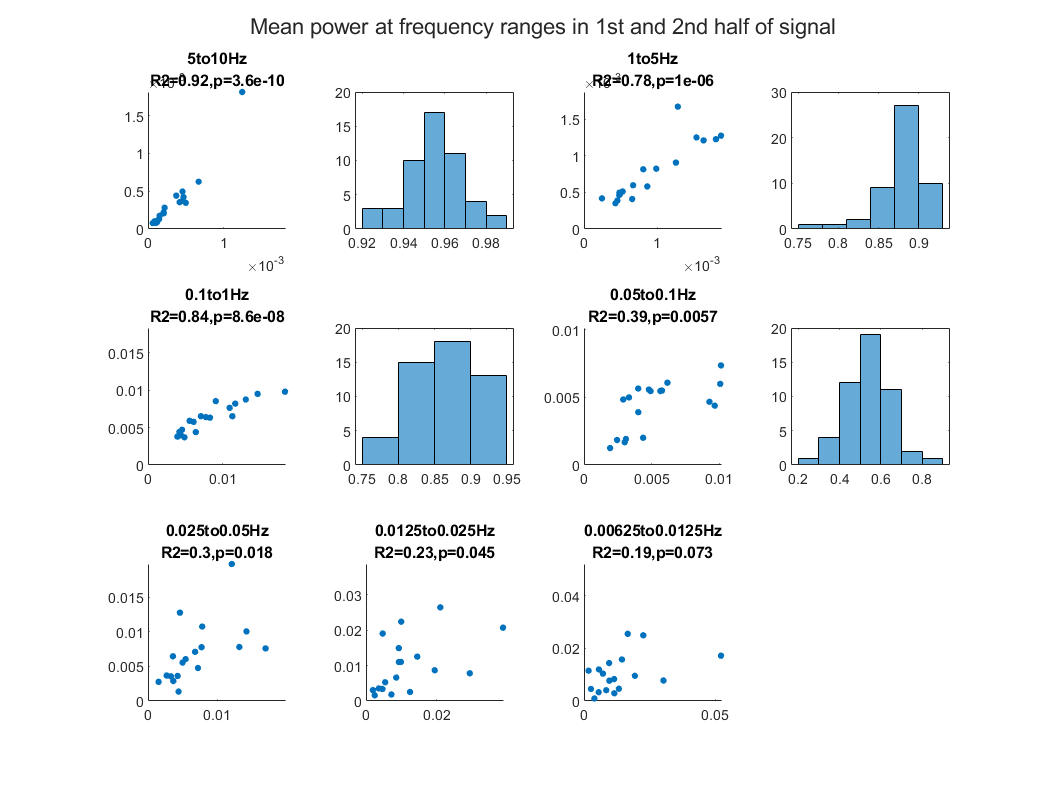

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
ncell=80;nsecond=60*10;
bpca=[];
for n=1:50 % 50 draws of cells 
    k=0;
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        for f=1:length(W)
            ca=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
            ca1 = ca(1:round(end/2)); % divide signal into two halves
            ca2 = ca(1+round(end/2):end);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p))
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in 1st and 2nd half of signal')

1.2 The mean power in 7 specified frequency ranges over first and second halves of the separation. Signals of 80 neurons in 9 minutes were taken from each animal. 

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
ncell=80;nsecond=60*9;
bpca=[];
for n=1:50 % 50 draws of cells 
    k=0;
for p=1:length(Es)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        for f=1:length(W)
            ca=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
            ca1 = ca(1:round(end/2)); % divide into two halves
            ca2 = ca(1+round(end/2):end);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end

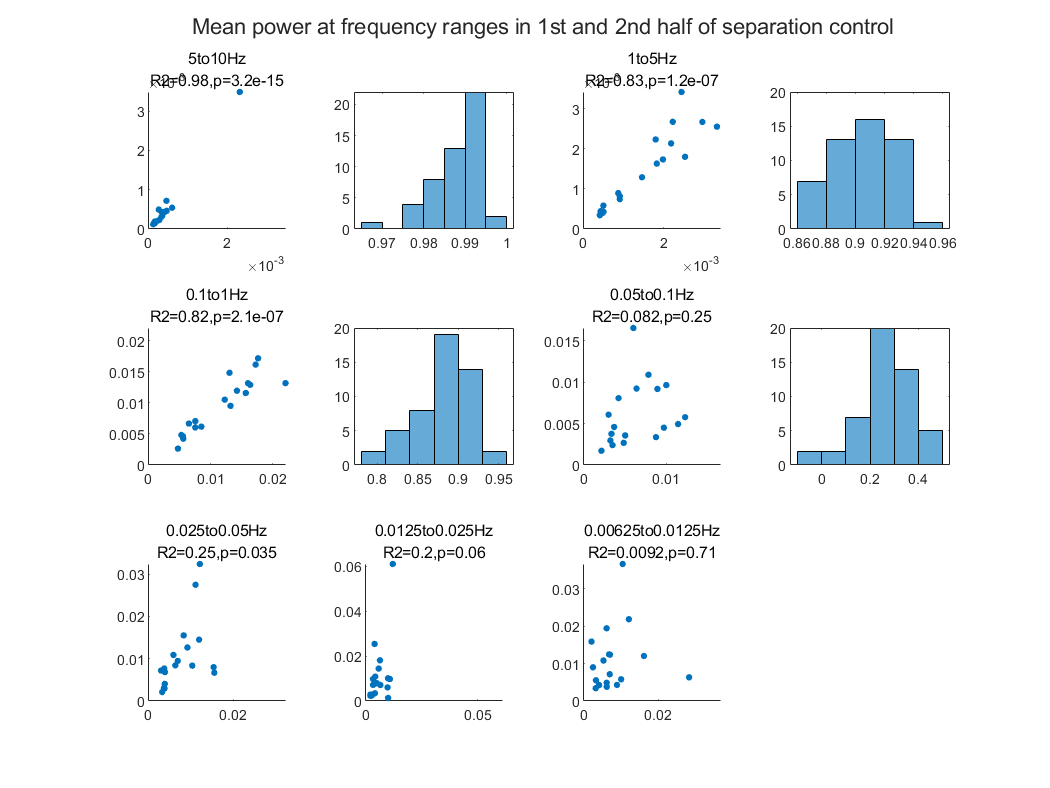

f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p),'FontWeight','normal','FontSize',8)
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in 1st and 2nd half of separation control')

1.3 The mean power in 7 specified frequency ranges over separation and experiment. Signals of 80 neurons in 5 minutes (sep and exp respectively) were taken from each animal. 

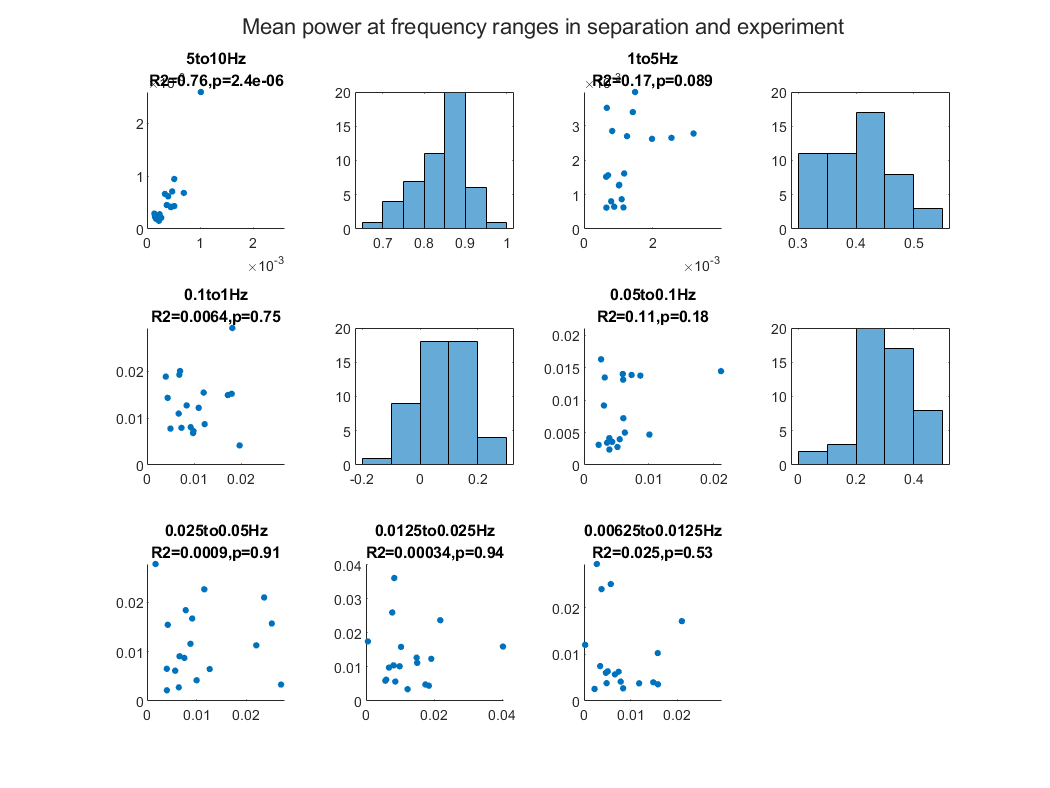

W = {[5 10] [1 5] [0.1 1] [0.05 0.1] [0.025 0.05] [0.0125 0.025] [0.00625 0.0125]};
close all 
ncell=80;nsecond=60*5;bpca=[];
for n=1:50
k=0;
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        [~,nce]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);rpe=randperm(nce);
        takecell=rp(1:ncell);takecelle=rpe(1:ncell);
        for f=1:length(W)
            ca1=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond/2,takecelle)),2); % mean of random cells in 7 minutes
            ca2=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond/2,takecell)),2);
            bpca(n,k,f,1)=bandpower(ca1,30,W{f});% mean power in specified ranges
            bpca(n,k,f,2)=bandpower(ca2,30,W{f});
        end
    end
end
end
f2=figure;f2.Position(3)=1.5*f2.Position(3);f2.Position(4)=1.5*f2.Position(4);
t=tiledlayout(3,4,'TileSpacing',"compact");
for f=1:length(W)
    nexttile
    x=mean(bpca(:,:,f,1));y=mean(bpca(:,:,f,2));
    scatter(x,y,15,'filled')
    xlim([0 max([x,y])]);ylim([0 max([x,y])])
    axis square 
    [r,p]=corr(x',y');r2=r.^2;
    title(sprintf('%gto%gHz\nR2=%.2g,p=%.2g',W{f}(1),W{f}(2),r2,p))
    if any(f==[1 2 3 4])
        nexttile
        h=corr(bpca(:,:,f,1)',bpca(:,:,f,2)');
        h=h(1:size(h,1)+1:end);
        histogram(h);
    end
end
title(t,'Mean power at frequency ranges in separation and experiment')

1.3 compare experiment and separation power 

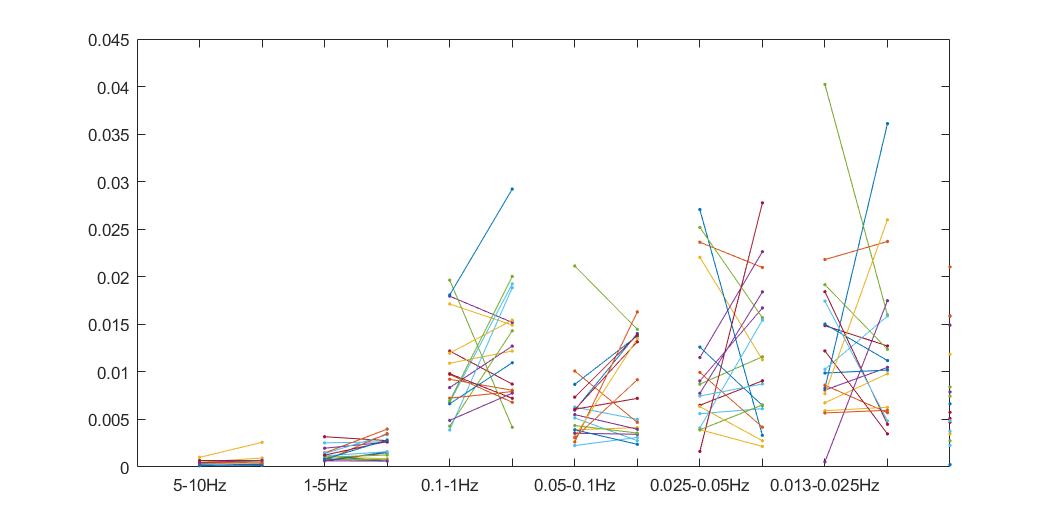

tlabel=strings(1,2*length(Ee));
f=figure;f.Position(3)=1.5*f.Position(3);
for f=1:length(W)
    % plot(repmat([2*f-1,2*f],2*length(Ee),1),squeeze(bpca(:,:,f))');
    plot([2*f-1,2*f],squeeze(mean(bpca(:,:,f,:))),'.-');xlim([0 13])
    hold on
    tlabel(2*f-1)=sprintf('%.2g-%.2gHz',W{f}(1),W{f}(2));
end
xticks(1:12);xticklabels(tlabel);

% for each frequency, first dot experiment, second dot separation

#### Power spectrum 

Power spectrum of the mean of 80 neurons from each animal between frequency 0.01-10Hz and 9 minutes. 

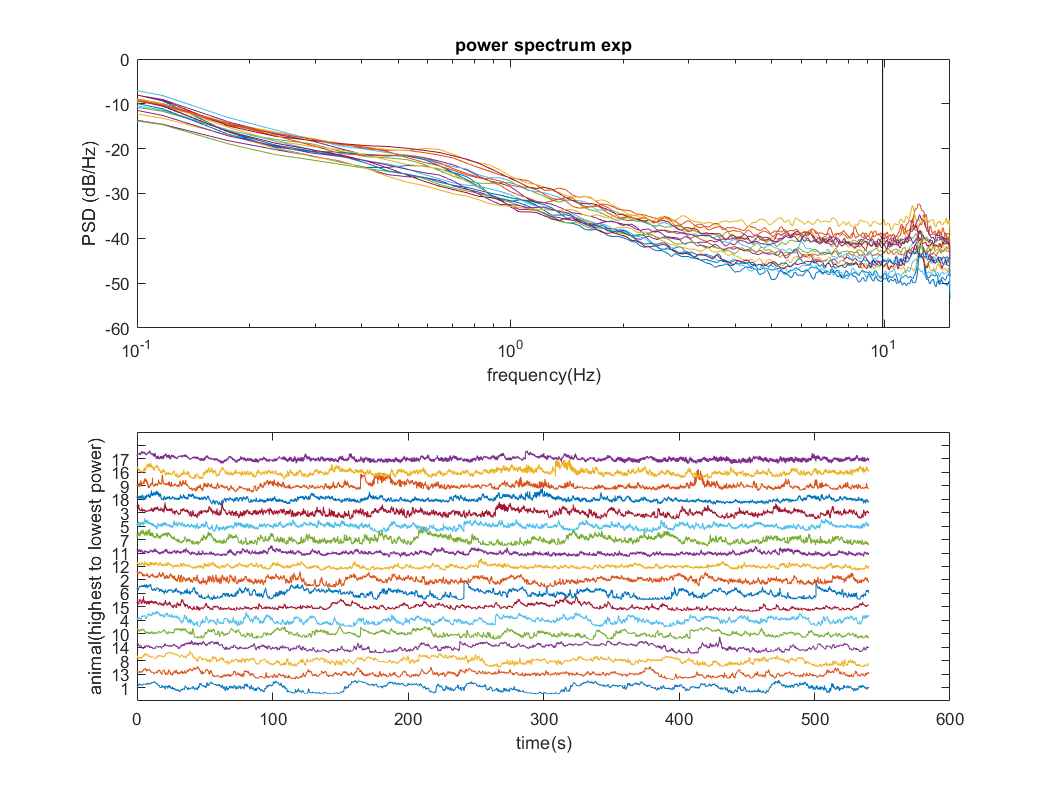

close all
ncell=80;nsecond=60*9;
k=0;ca=[];
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Ee{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        ca(k,:)=mean(zscore(Ee{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
        [pxx(k,:),fre]=pwelch(ca(k,:),30*10,[],[],30);
        subplot(2,1,1)
        plot(fre,10*log10(pxx(k,:)))
        hold on 
    end
end
xlim([0.1 15]);set(gca,'xscale','log');xlabel('frequency(Hz)');ylabel('PSD (dB/Hz)')
line([fre(170),fre(170)],ylim,'color','k');
hold off
title('power spectrum exp')
[~,ind]=sort(pxx(:,170));% sort at ~ frequency 10Hz
subplot(2,1,2)
plot(1/30:1/30:nsecond,ca(ind,:)'+repelem(1:N*2,length(ca),1));xlabel('time(s)');ylabel('animal(highest to lowest power)');
yticks(1:N*2+1);yticklabels(ind)

separation control 

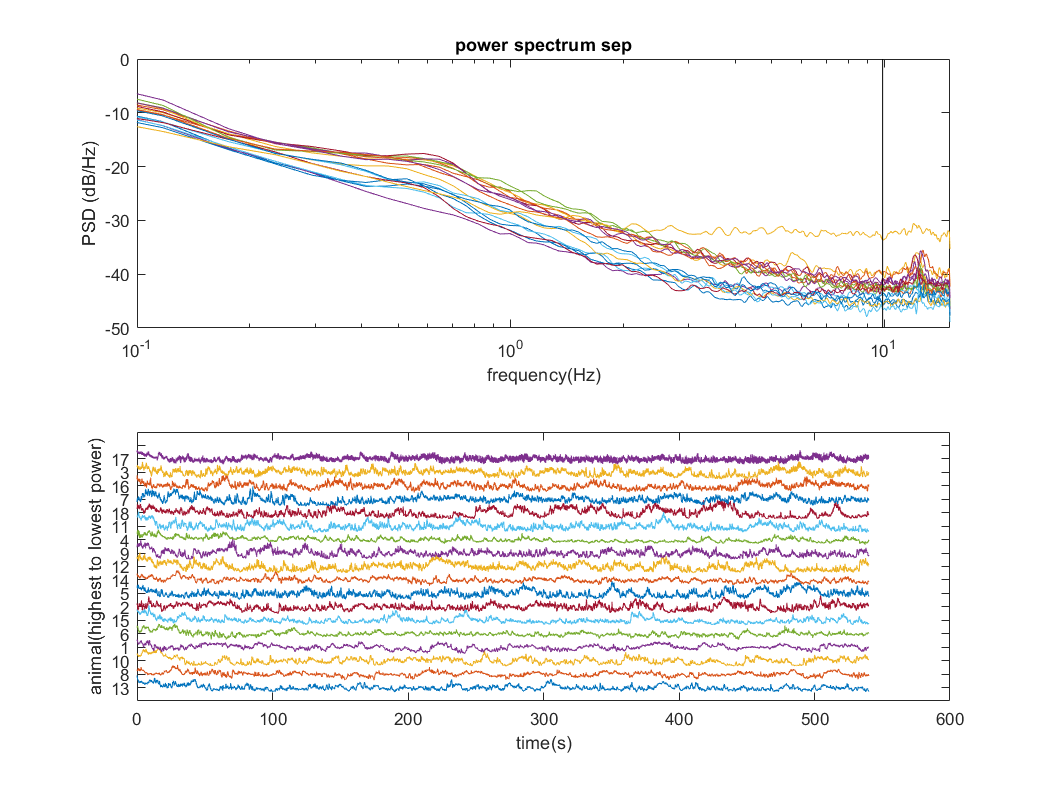

close all
ncell=80;nsecond=60*9;
k=0;
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.5*f.Position(4);
for p=1:length(Ee)
    for m=1:2
        [nf,nc]=size(Es{p}{m}.dFFCalciumTraces);
        if nc<ncell||nf<=nsecond*30
            sprintf('not enough data pair%dmouse%d',p,m)
            continue
        end
        k=k+1;
        rp=randperm(nc);
        takecell=rp(1:ncell);
        ca(k,:)=mean(zscore(Es{p}{m}.dFFCalciumTraces(1:30*nsecond,takecell)),2); % mean of 75 random cells in 10 minutes
        [pxx(k,:),fre]=pwelch(ca(k,:),30*10,[],[],30);
        subplot(2,1,1)
        plot(fre,10*log10(pxx(k,:)))
        hold on 
    end
end
xlim([0.1 15]);set(gca,'xscale','log');xlabel('frequency(Hz)');ylabel('PSD (dB/Hz)')
line([fre(170),fre(170)],ylim,'color','k');
hold off
title('power spectrum sep')
[~,ind]=sort(pxx(:,170));% sort at ~ frequency 10Hz
subplot(2,1,2)
plot(1/30:1/30:nsecond,ca(ind,:)'+repelem(1:N*2,length(ca),1));xlabel('time(s)');ylabel('animal(highest to lowest power)');
yticks(1:N*2+1);yticklabels(ind)